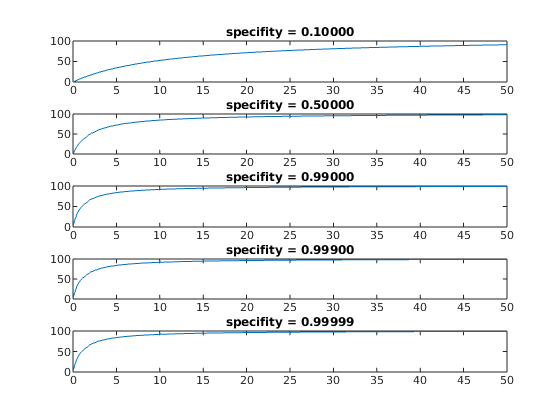

pI = [0.1 0.5 0.99 0.999 0.99999]; % positive test, when infected
I = [0.001:0.001:0.009 0.01:0.01:0.09 0.1:0.1:0.9 1:50]./100; % infected
pH = 1-0.99;% positive test, when healthy

probI_P =@(pIvar) pIvar.*I./(pIvar.*I+pH*(1-I)); % probability formula

% plot
figure(1)
for ii=1:length(pI)
    iP = probI_P(pI(ii));
    subplot(length(pI),1,ii)
    plot(I*100,iP*100)
    ylim([0,100])
    title(sprintf('specifity = %1.5f',pI((ii))))
end

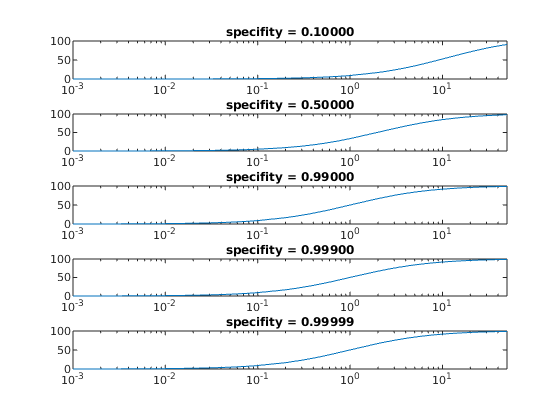


% plot with logarithmic x-axis
figure(2)
for ii=1:length(pI)
    iP = probI_P(pI(ii));
    subplot(length(pI),1,ii)
    semilogx(I*100,iP*100)
    xlim([1e-3,50])
    ylim([0,100])
    title(sprintf('specifity = %1.5f',pI((ii))))
end